# Modeling Mean Flight Speed

## 1. Import and create data

clear all; load('./data/dc_corr.mat'); load coastlines; addpath('functions/'); warning('off')

Convert the volumetric speed to a surface speed (`denss`)

for i=1:numel(dc)
    tmp=diff(double([0 max(0, (1:dc(i).levels).*dc(i).interval - dc(i).height )]))/1000;
    nb_bird=dc(i).dens .* repmat(tmp,size(dc(i).dens,1),1);
    dc(i).denss = sum(nb_bird,2);
    nb_bird(isnan(dc(i).ff))=0;
    dc(i).ffs = nansum(dc(i).ff.*nb_bird,2)./sum(nb_bird,2);
    % Previous dc(i).dds2 = nansum(dc(i).dd.*nb_bird,2)./sum(nb_bird,2);    
    alpha = deg2rad(dc(i).dd);
    %w_MTR = dc(i).ff.* nb_bird ./ repmat(nansum(dc(i).ff.*nb_bird,2),1,size(dc(i).dens,2));
    w_MTR =nb_bird ./ repmat(nansum(nb_bird,2),1,size(dc(i).dens,2));
    r = nansum(w_MTR.*exp(1i*alpha),2);
    dc(i).dds = rad2deg(atan2(imag(r), real(r)));
    dc(i).dds = mod(dc(i).dds,360);
    dc(i).scoret = datenum(dc(i).time'-mean([dc(i).sunrise;dc(i).sunset])) ./ datenum(dc(i).sunrise-dc(i).sunset)*2;
end

Create the data structure `data`

dens_lim = 0;
ffs_lim = 0;
data=[];
uniqueDate = round(datenum(datetime(start_date-1:end_date-1)));
for i=1:numel(dc)
    id = dc(i).scoret(:)>=-1 & dc(i).scoret(:)<=1 & dc(i).denss>dens_lim & dc(i).ffs>ffs_lim;
    d=table();
    d.ff=dc(i).ffs(id);
    d.dd=dc(i).dds(id);
    d.dens=dc(i).denss(id);
    d.scoret = dc(i).scoret(id)';
    d.i_r=i*ones(sum(id),1);
    d.lat=dc(i).lat*ones(sum(id),1);
    d.lon=dc(i).lon*ones(sum(id),1);
    d.time = datenum(dc(i).time(id));
    tmp = round(datenum(dc(i).sunrise(id)))';
    [~,id]=ismember(tmp,uniqueDate);
    d.dateradar = sub2ind([numel(dc) numel(uniqueDate)],repmat(i,numel(tmp),1),id);
    data = [data ; d ];
end

clear d dens_lim 

## 2. Transformation of data

Center the data, so that the transform variable is the difference from the mean direction of migration. Send value above 180 deg or below -180 to their other value on the circle.

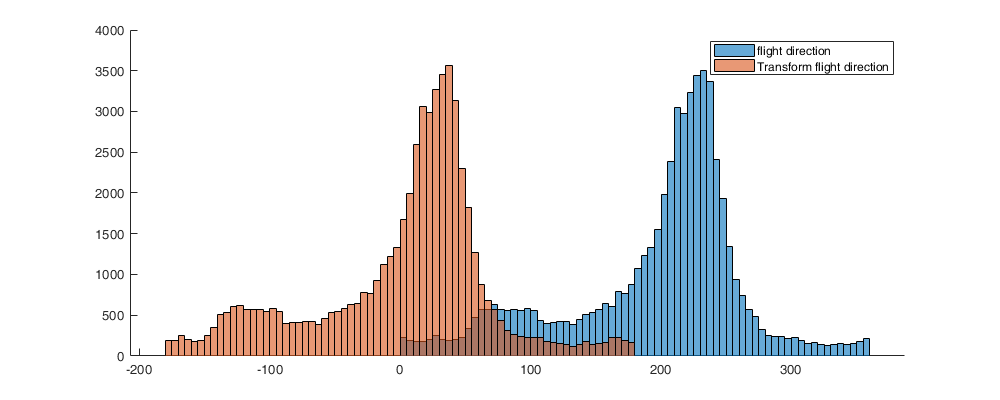

data.ddtrans = data.dd-mean(data.dd);
data.ddtrans(data.ddtrans>180)=data.ddtrans(data.ddtrans>180)-360;
data.ddtrans(data.ddtrans<-180)=data.ddtrans(data.ddtrans<-180)+360;

figure('position',[0 0 1000 400]); hold on;
histogram(data.dd); histogram(data.ddtrans)
legend('flight direction','Transform flight direction')

We can test wheather the distribution of each radar is the same.

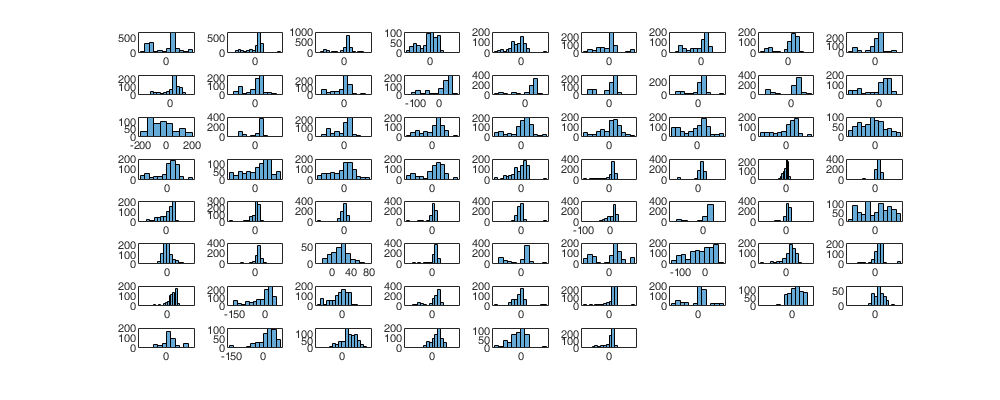

figure('position',[0 0 1000 400]); hold on;
for i=1:numel(dc)
    subplot(8,9,i); histogram(data.ddtrans(data.i_r==i))
end

## 3. Amplitude, trend and cuve fitting -- NOT USE!!!

Check for a spatially-stationary field

% S=nan(1,numel(dc));
% for i=1:numel(dc)
%     S(i)=mean(data.ddtrans(data.i_r==i));
% end
% figure('position',[0 0 1000 400]);  
% subplot(1,2,1); hold on; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  
% scatterm([dc.lat],[dc.lon],[dc.maxrange]*4,S,'filled','MarkerEdgeColor','k'); title('Normalized Average Direction per radar'); 
% plotm(coastlat, coastlon,'k');colorbar;

Check for a temporal-stationary field. NOT TEMPORALLY STATIONARY

% figure('position',[0 0 1000 400]); hold on;
% for i=1:numel(dc)
%     plot(data.time(data.i_r==i), data.ddtrans(data.i_r==i),'.');
% end

Compute the Amplitude

% ampli.A=zeros(numel(dc), numel(uniqueDate));
% for i=1:numel(ampli.A)
%     ampli.A(i)=mean(data.ddtrans(data.dateradar==i));
% end
% figure('position',[0 0 1000 600]);  c_caxis=[min(ampli.A(:)) max(ampli.A(:))];
% for i = 1:numel(uniqueDate)
%     subplot(4,6,i); hold on; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  plotm(coastlat, coastlon,'k')
%     scatterm([dc.lat],[dc.lon],[dc.maxrange]*4,ampli.A(:,i),'filled','MarkerEdgeColor','k');
%     caxis(c_caxis);
% end

Compute the Residual and check for its distribution. Wider variance at the begingin and end of night. Curve not necessary

% res.r = data.ddtrans-ampli.A(data.dateradar);
% curve.p = polyfit(data.scoret,res.r(:),5);
% res.p = polyfit(data.scoret,res.r(:).^2,5);
% 
% figure('position',[0 0 1000 400]); hold on; plot(data.scoret,res.r,'.k');
% plot(data.scoret,sqrt(polyval(curve.p,data.scoret)),'.r');
% plot(data.scoret,sqrt(polyval(res.p,data.scoret)),'.r'); plot(data.scoret,-sqrt(polyval(res.p,data.scoret)),'.r');
% xlabel('Noramlized night (-1: sunset | 1: sunrise)'); ylabel('row data-Amplitude [m/s]'); ylim([-60 60])
% figure('position',[0 0 1000 400]); hold on; plot(data.ddtrans,'k'); plot(ampli.A(data.dateradar),'r'); 
% xlabel('Time | radars (signal of all radars juxtaposed)'); ylabel('Amplitude of the night [m/s]'); legend('Data','Prediction')
% figure('position',[0 0 1000 400]); hold on; ylabel('Histogram des residus')
% histogram(data.ddtrans-ampli.A(data.dateradar)); 

## 5.2 Built matrix of distance

Built the matrix of distances of the data. Distence (or difference) in lattitude, longitude, time and value. 

dir.ddn=data.ddtrans;

Ddist_sf=squareform(pdist(repmat([[dc.lat]' [dc.lon]'], numel(uniqueDate),1),@lldistkm));

dir.D=table();

for i=1:numel(uniqueDate)
    d=table();
    
    id  = find(ismember( data.dateradar, sub2ind([numel(dc), numel(uniqueDate)],1:numel(dc),i*ones(1,numel(dc)))));

    d.Ddist = reshape(Ddist_sf(data.i_r(id),data.i_r(id)'),[],1);
    d.Dtime = reshape(squareform(pdist(data.time(id))),[],1);
    d.Did1 = repmat(id,numel(id),[]);
    d.Did2 = repelem(id,numel(id));
    
    dir.D=[dir.D ; d];
end

## 5.3 Empirical Variogram

dir.cov.d=[0 100 200 300 600 1000 1500 2000 3000];
dir.cov.t=[0 .01 .02 .05 .07 .1 .15 .2 .25 .3 .35 .4 .45]; 
[dir.cov.D,dir.cov.T]=meshgrid(dir.cov.d(1:end-1)+diff(dir.cov.d)/2,dir.cov.t(1:end-1)+diff(dir.cov.t)/2);

dir.cov.emp_grid=nan(size(dir.cov.D));

for i_d=1:numel(dir.cov.d)-1
    id1 = find(dir.D.Ddist>=dir.cov.d(i_d) & dir.D.Ddist<dir.cov.d(i_d+1));
    for i_t=1:numel(dir.cov.t)-1
        id2 = id1(dir.D.Dtime(id1)>=dir.cov.t(i_t) & dir.D.Dtime(id1)<dir.cov.t(i_t+1));
        % dir.cov.emp_grid(i_t,i_d)=mean(dir.ddn(dir.D.Did1(id2)) .* dir.ddn(dir.D.Did2(id2)));
        delta_dnn = dir.ddn(dir.D.Did1(id2)) - dir.ddn(dir.D.Did2(id2));
        delta_dnn(delta_dnn>180)=delta_dnn(delta_dnn>180)-360;
        delta_dnn(delta_dnn<-180)=delta_dnn(delta_dnn<-180)+360;
        dir.cov.emp_grid(i_t,i_d)=1/2*mean( (delta_dnn).^2 );
    end
end

Figure

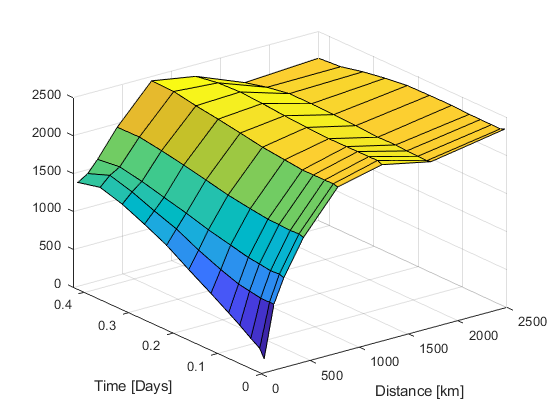

figure; surf(dir.cov.D,dir.cov.T,dir.cov.emp_grid);  xlabel('Distance [km]'); ylabel('Time [Days]');

## 5.4 Calibrate ampli.cov.parmriance 

Gneiting = @(dist,time,range_dist,range_time,delta,gamma,beta) 1./( (time./range_time).^(2.*delta) +1 ) .* exp(-(dist./range_dist).^(2.*gamma)./((time./range_time).^(2.*delta) +1).^(beta.*gamma) );
Gneiting_fit = @(parm) parm(1) + parm(2) - parm(2).*Gneiting(dir.cov.D(:),dir.cov.T(:),parm(3),parm(4),parm(5),parm(6),parm(7));

dir.cov.parm0 =[.5 .5 500 5 .5 .5 .5];
dir.cov.parm_min=[0 0 0.0001 0 0 0 0 ]';
dir.cov.parm_max=[nancov(dir.ddn) 2*nancov(dir.ddn) 3000 10 1 1 1]';

rmse = @(parm) sum( ( Gneiting_fit(parm) -  dir.cov.emp_grid(:) ).^2 );
dir.cov.parm = fmincon(rmse,dir.cov.parm0,[],[],[],[],dir.cov.parm_min,dir.cov.parm_max,[]);% ,optimset('PlotFcn',@optimplotfval)


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the default value of the step size tolerance and constraints are 
satisfied to within the default value of the constraint tolerance.

<stopping criteria details>



%dir.cov.parm(1) = nancov(dir.ddn)-dir.cov.parm(2);
sprintf('%.3f ',dir.cov.parm)

ans = '243.852 2039.616 387.507 0.355 0.683 0.724 0.219 '

Figure

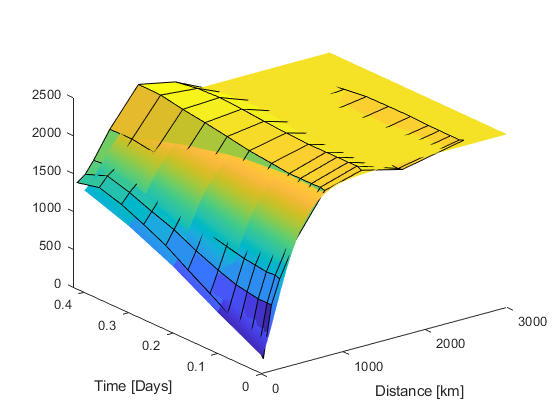

[tmpD,tmpT] = meshgrid(dir.cov.d(1):1:dir.cov.d(end),dir.cov.t(1):0.1:dir.cov.t(end));
tmpCOV=dir.cov.parm(1)+dir.cov.parm(2)-dir.cov.parm(2).*Gneiting(tmpD(:), tmpT(:), dir.cov.parm(3), dir.cov.parm(4), dir.cov.parm(5), dir.cov.parm(6), dir.cov.parm(7));
tmpCOV=reshape(tmpCOV,size(tmpD,1),size(tmpD,2));
figure; hold on;
s=surf(tmpD,tmpT,tmpCOV);
surf(dir.cov.D,dir.cov.T,dir.cov.emp_grid);  xlabel('Distance [km]'); ylabel('Time [Days]');
s.EdgeColor='none'; view(3)

## 5.5 Kriging residual

dir.cov.C = dir.cov.parm(2).*Gneiting(dir.D.Ddist, dir.D.Dtime, dir.cov.parm(3), dir.cov.parm(4), dir.cov.parm(5), dir.cov.parm(6), dir.cov.parm(7));
dir.cov.C = sparse(dir.D.Did1,dir.D.Did2,dir.cov.C);
dir.cov.C = dir.cov.C + spdiags(repmat(dir.cov.parm(1),size(dir.cov.C,1),1),0,size(dir.cov.C,1),size(dir.cov.C,2));

dir.ddn_est=nan(size(dir.ddn));
dir.ddn_sig=nan(size(dir.ddn));

k=100;

for i_d=1:numel(uniqueDate)
    neigh  = find(ismember( data.dateradar, sub2ind([numel(dc), numel(uniqueDate)],1:numel(dc),i_d*ones(1,numel(dc)))));

    for i_s=1:numel(neigh)
        
        neigh_s = neigh(data.dateradar(neigh)~=data.dateradar(neigh(i_s)));
        Cab = full(dir.cov.C(neigh_s,neigh(i_s)));
        [~,id]=maxk(Cab,k);
        neigh_s=neigh_s(id);

            % Simple
            % lambda = dir.cov.C(neigh_s,neigh_s) \ dir.cov.C(neigh_s,neigh(i_s));
            % dir.ddn_est(neigh(i_s)) =  lambda' * dir.ddn(neigh_s);
            % dir.ddn_sig(neigh(i_s)) = dir.cov.parm(1) + dir.cov.parm(2) - lambda' * dir.cov.C(neigh_s,neigh(i_s));
            
            % Ordinary
            lambda = [dir.cov.C(neigh_s,neigh_s) ones(numel(neigh_s),1); ones(1,numel(neigh_s)) 0] \ [ dir.cov.C(neigh_s,neigh(i_s)) ; 1];
            dir.ddn_est(neigh(i_s)) = lambda(1:end-1)' * dir.ddn(neigh_s);
            dir.ddn_sig(neigh(i_s)) = sqrt( dir.cov.parm(1) + dir.cov.parm(2) - lambda' * [dir.cov.C(neigh_s,neigh(i_s)); 1] );
            
            % figure; hold on;
            % scatter3(data.lon(i),data.lat(i),data.time(i),'r','filled')
            % % scatter3(data.lon(neigh),data.lat(neigh),data.time(neigh),[],Cab,'filled')
            %  scatter3(data.lon(neigh),data.lat(neigh),data.time(neigh),[],lambda,'filled')
    end
end

Figure

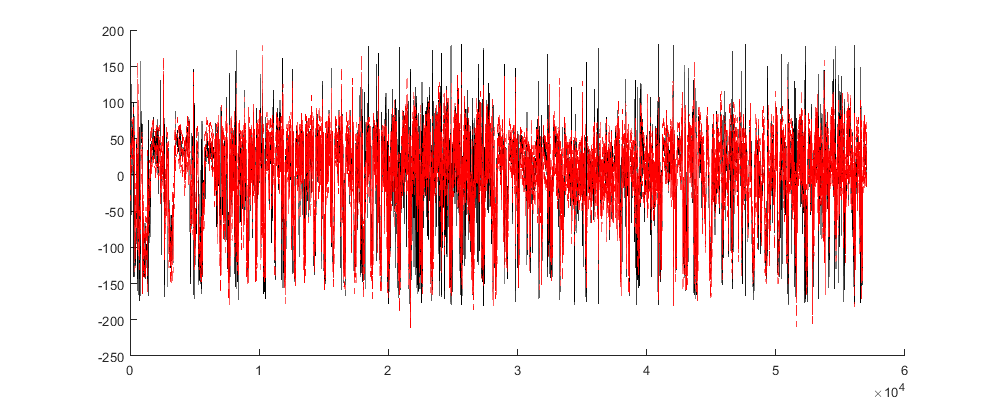

figure('position',[0 0 1000 400]); hold on;
plot(dir.ddn,'k');
plot(dir.ddn_est,'r');
plot(dir.ddn_est-dir.ddn_sig,'--r')
plot(dir.ddn_est+dir.ddn_sig,'--r')

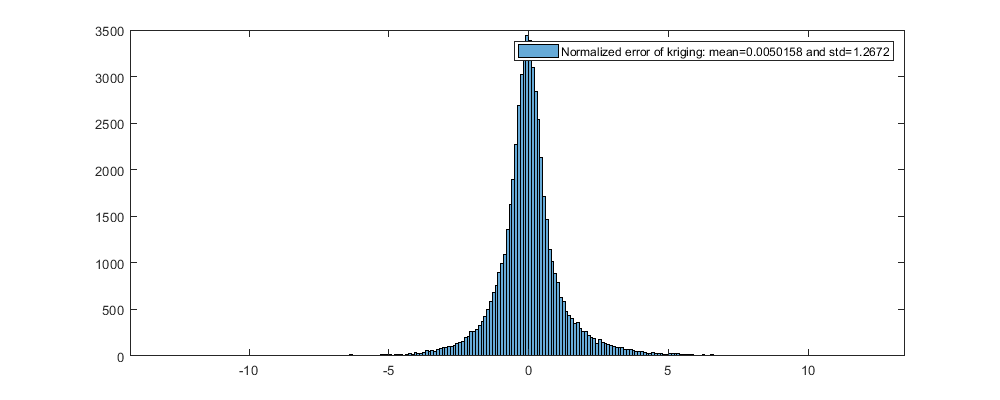

err_norm = (dir.ddn_est-dir.ddn)./(dir.ddn_sig);
figure('position',[0 0 1000 400]); histogram( err_norm );
legend(['Normalized error of kriging: mean=' num2str(mean((dir.ddn_est-dir.ddn)./(dir.ddn_sig))) ' and std=' num2str(std((dir.ddn_est-dir.ddn)./(dir.ddn_sig)))]);

## 5.6 Back Normalized

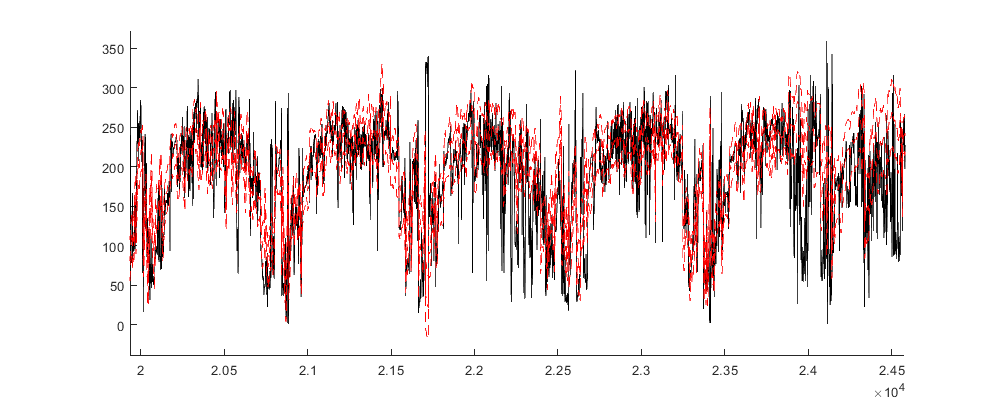

dir.dd_est = dir.ddn_est+mean(data.dd);
dir.dd_sig = dir.ddn_sig;


figure('position',[0 0 1000 400]); hold on;
plot(data.dd,'-k')
plot(dir.dd_est,'--r')
plot(dir.dd_est-dir.dd_sig,'--r')
plot(dir.dd_est+dir.dd_sig,'--r')

sqrt(mean( (dir.ddn_est-dir.ddn ).^2 ))

ans = 35.1423

sqrt(mean( (dir.dd_est-data.dd ).^2 ))

ans = 35.1022

for i_r=1:numel(dc)
    dir_dd_est_avg(i_r) = mean(dir.dd_est(data.i_r==i_r));
    dir_dd_avg(i_r) = mean(data.dd(data.i_r==i_r));
end
dir_avg_err=dir_dd_est_avg-dir_dd_avg

figure('position',[0 0 1000 400]);  
subplot(1,2,1); hold on; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  
plotm(coastlat, coastlon,'k')
scatterm([dc.lat],[dc.lon],[dc.maxrange]*4,dir_dd_est_avg,'filled','MarkerEdgeColor','k'); title('Mean normalized error of kriging'); colorbar;
subplot(1,2,2); hold on; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  
plotm(coastlat, coastlon,'k')
scatterm([dc.lat],[dc.lon],[dc.maxrange]*4,dir_dd_est_avg,'filled','MarkerEdgeColor','k'); title('Std dev normalized error of kriging'); colorbar;

## 7. Save

save('data/FlightDir_modelInf.mat','data','dir','-v7.3')
% load('data/FlightDir_modelInf.mat')